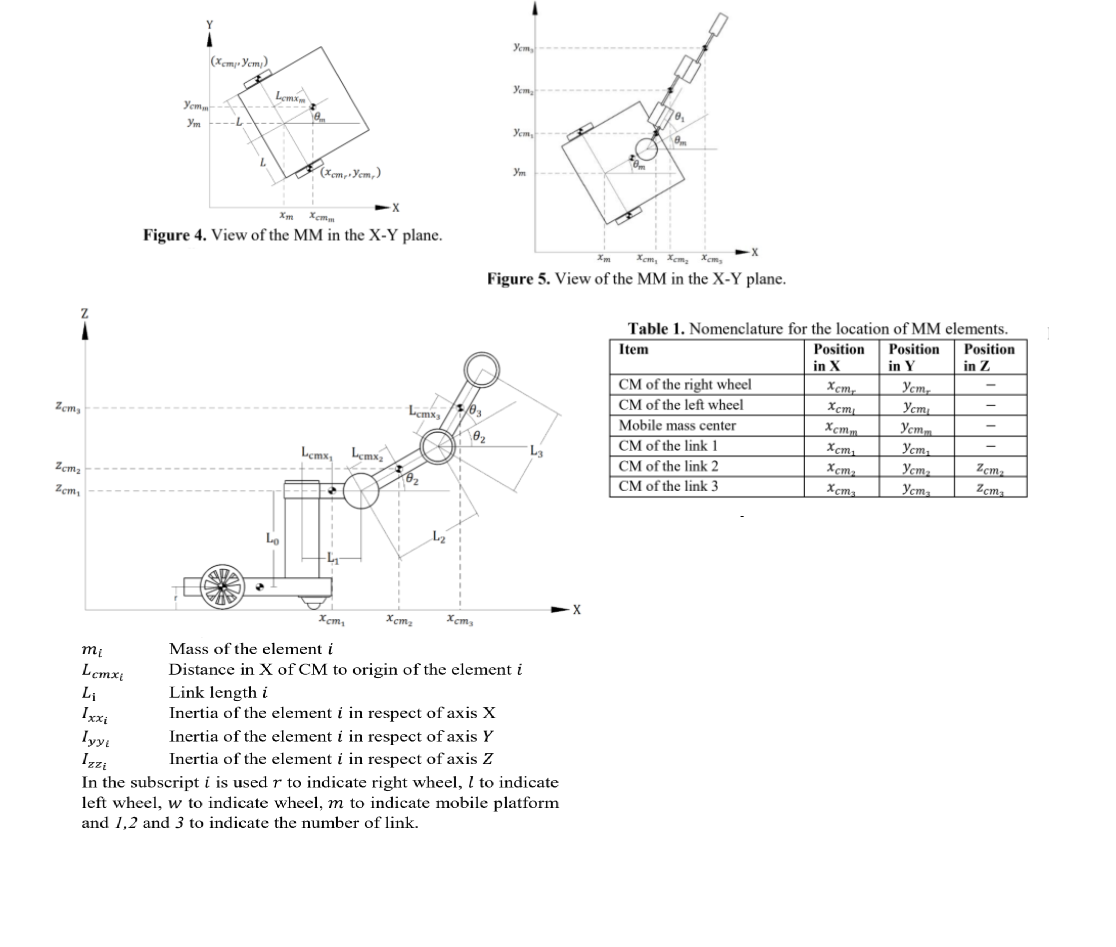

From equation (39) to (52) the positions of the bodies that make up the robot are presented; these equations are used to determine the kinetic and potential energy of the system.

clc; clearvars; close all;

%% Time + generalized coordinates
syms t real
syms x_m(t) y_m(t) theta_m(t) theta_r(t) theta_l(t)

%% Geometry (lengths, SI)
syms L d r L_cmx_m real
assumeAlso([L d r L_cmx_m] > 0)

%% Trig shorthands
cm  = cos(theta_m(t)); 
sm  = sin(theta_m(t));

%% (39)–(44): COM positions (wheels + base)
x_cm_r = x_m(t) + L*sm;                 y_cm_r = y_m(t) - L*cm;
x_cm_l = x_m(t) - L*sm;                 y_cm_l = y_m(t) + L*cm;
x_cm_m = x_m(t) + L_cmx_m*cm;           y_cm_m = y_m(t) + L_cmx_m*sm;

COM = struct( ...
  'x_cm_r',x_cm_r,'y_cm_r',y_cm_r, ...
  'x_cm_l',x_cm_l,'y_cm_l',y_cm_l, ...
  'x_cm_m',x_cm_m,'y_cm_m',y_cm_m);

%% Generalized coordinates and velocities
q  = [x_m; y_m; theta_m; theta_r; theta_l];
qd = diff(q,t);

vel = @(p) jacobian(p,q)*qd;

v_cmr = vel([x_cm_r; y_cm_r]);
v_cml = vel([x_cm_l; y_cm_l]);
v_cmm = vel([x_cm_m; y_cm_m]);

%% Angular rates
w_m = diff(theta_m,t);   % base yaw
w_r = diff(theta_r,t);   % right wheel spin
w_l = diff(theta_l,t);   % left wheel spin

%% Parameters: masses & inertias
syms m_w m_m real
syms I_yyw I_zzw I_m real
assumeAlso([m_w m_m I_yyw I_zzw I_m] > 0)

%% Speed^2 helper
speed2 = @(v) simplify(v.'*v, 'Steps', 50);

v2_cmr = speed2(v_cmr);
v2_cml = speed2(v_cml);
v2_cmm = speed2(v_cmm);

%% Kinetic energies (platform + wheels)
% Interpretation:
% - I_yyw: inertia about wheel spin axis
% - I_zzw: inertia about vertical axis through wheel center
% - Each wheel: translational KE + spin about axle + yaw with base
K_r = 1/2*m_w*v2_cmr + 1/2*I_yyw*w_m^2 + 1/2*I_zzw*w_r^2;
K_l = 1/2*m_w*v2_cml + 1/2*I_yyw*w_m^2 + 1/2*I_zzw*w_l^2;

% Mobile platform body
K_m = 1/2*m_m*v2_cmm + 1/2*I_m*w_m^2;

% Total kinetic energy
K = simplify(K_r + K_l + K_m, 'Steps', 100);

%% Potential energy (planar base: zero)
syms g real
U = sym(0);

%% Lagrangian
Lagr = simplify(K - U, 'Steps', 50);

%% Euler–Lagrange equations (unconstrained)
tau = simplify( diff(gradient(Lagr, qd), t) - gradient(Lagr, q), 'Steps', 50 )

$$tau(t) = \begin{array}{l} \left(\begin{array}{c} m_{m}\,\sigma_{3}+2\,m_{w}\,\sigma_{3}-L_{\mathrm{cmx},m}\,m_{m}\,\cos\left(\theta_{m}\left(t\right)\right)\,\sigma_{4}-L_{\mathrm{cmx},m}\,m_{m}\,\sin\left(\theta_{m}\left(t\right)\right)\,\sigma_{1}\\ m_{m}\,\sigma_{2}+2\,m_{w}\,\sigma_{2}-L_{\mathrm{cmx},m}\,m_{m}\,\sin\left(\theta_{m}\left(t\right)\right)\,\sigma_{4}+L_{\mathrm{cmx},m}\,m_{m}\,\cos\left(\theta_{m}\left(t\right)\right)\,\sigma_{1}\\ I_{m}\,\sigma_{1}+2\,I_{\mathrm{yyw}}\,\sigma_{1}+2\,L^{2}\,m_{w}\,\sigma_{1}+{L_{\mathrm{cmx},m}}^{2}\,m_{m}\,\sigma_{1}+L_{\mathrm{cmx},m}\,m_{m}\,\cos\left(\theta_{m}\left(t\right)\right)\,\sigma_{2}-L_{\mathrm{cmx},m}\,m_{m}\,\sin\left(\theta_{m}\left(t\right)\right)\,\sigma_{3}\\ I_{\mathrm{zzw}}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right)\\ I_{\mathrm{zzw}}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{m}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}y_{m}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}x_{m}\left(t\right)\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta_{m}\left(t\right)\right)}^{2} \end{array}$$